# Noise Variances

% Run script
run('Noise_estimation.m');

Launching ROS Core...
.Done in 1.8029 seconds.
Initializing ROS master on http://12.0.10.178:11311.
Initializing global node /matlab_global_node_77981 with NodeURI http://Gioels-MBP:49920/ and MasterURI http://localhost:11311.


Error using Noise_estimation
Cannot determine the message type of the /qualisys/Super_marker_1/odom topic. Either the topic is not registered with the ROS master, or the ROS master is not reachable.

Error in run (line 91)
evalin('caller', strcat(script, ';'));

# Mex functions generation

#### FORWARD KINEMATICS


$$\pmatrix{p_{1} \cr P_{2} \cr .. \cr P_{M}} = \pmatrix{\Phi_1(q) \cr \Phi_2(q) \cr ..  \cr \Phi_M(q) } \qquad \Longrightarrow \qquad  p = \Phi(q)$$


#### JACOBIAN COMPUTATION


$$\pmatrix{\dot{p}_{1} \cr \dot{p}_{2} \cr .. \cr \dot{p}_{M}} = \pmatrix{J_1(q) \cr J_2(q) \cr ..  \cr J_M(q) } \cdot \dot{q} \qquad \Longrightarrow \qquad  \tilde{u} = J(q) \cdot  \dot{q} $$


% Clear variables
clear;
clear global;
close all;
clc;

% Run trajectory
load('q_trajectory.mat');

% Run human_arm_parameters
run('human_arm_parameters.m');

% Run script
mex_generation(arm.markers.links, sample_Time, 'false');

% See if any singularities are present
max_number_simulations = 1000;
singular_config(q_trajectory, shoulder_num, forearm_num, hand_num, 1e-10, max_number_simulations);

Set of SHOULDER markers:-0.048303
Set of SHOULDER markers:-0.033842
Set of SHOULDER markers:-0.012914
Set of FOREARM markers:0.015634
Set of FOREARM markers:-0.01203
Set of FOREARM markers:0.025604
Set of HAND markers:-0.02654   -0.039217
Set of HAND markers: -0.1594   -0.080954
Set of HAND markers:    0.03        0.03


# LS APPROACH


$$\dot{q} = J^{\dagger}(q) \cdot  \tilde{u} \qquad \longrightarrow \qquad \tilde{u} = \dot{p}$$


% Clear variables
clear;
clear global;
close all;
clc;

% Run trajectory
load('q_trajectory.mat');

% Human arm parameters
run('human_arm_parameters.m');

## 1.  PERFECT GUESS OF INITIAL CONDITION q0 

% Model IC 
q0_model = q_trajectory.signals.values(1, :)';

% LS IC
q0_LS = q0_model;

% Results
LS_KF_EKF_NLDM("LS", 'precomputed', [], [], 'S1_F1_H2');

aaa
aaa


Error using LS_KF_EKF_NLDM
Invalid setting in block 'master_thesis_simulink/System/Constant1' for parameter 'Value'

## 2.  WRONG GUESS OF INITIAL CONDITION q0 

ADJOINT


   1.0e-08 *

    0.0293   -0.0905    0.0000   -0.0837    0.0543    0.0905   -0.0000
   -0.0905    0.2791   -0.0000    0.2580   -0.1675   -0.2791    0.0000
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
   -0.0837    0.2580   -0.0000    0.2385   -0.1548   -0.2580    0.0000
    0.0543   -0.1675   -0.0000   -0.1548    0.1005    0.1675    0.0000
    0.0905   -0.2791    0.0000   -0.2580    0.1675    0.2791   -0.0000
   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000

DET
  -3.2316e-25

Time
     0



ADJOINT


   1.0e-08 *

    0.0293   -0.0905    0.0000   -0.0837    0.0543    0.0905   -0.0000
   -0.0905    0.2791   -0.0000    0.2580   -0.1675   -0.2791    0.0000
    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
   -0.0837    0.2580   -0.0000    0.2385   -0.1548   -0.2580    0.0000
    0.0543   -0.1675    0.0000   -0.1548    0.1005    0.1675   -0.0000
    0.0905   -0.2791    0.0000   -0.2580    0.1675    0.2791   -0.0000
   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000

DET
   3.0259e-26

Time
     0



ADJOINT


   1.0e-08 *

    0.0293   -0.0905    0.0000   -0.0837    0.0543    0.0905   -0.0000
   -0.0905    0.2791   -0.0000    0.2580   -0.1675   -0.2791    0.0000
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
   -0.0837    0.2580   -0.0000    0.2385   -0.1548   -0.2580    0.0000
    0.0543   -0.1675   -0.0000   -0.1548    0.1005    0.1675    0.0000
    0.0905   -0.2791    0.0000   -0.2580    0.1675    0.2791   -0.0000
   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000

DET
  -3.2316e-25

Time
     0



ADJOINT


   1.0e-08 *

    0.0293   -0.0905   -0.0000   -0.0837    0.0543    0.0905    0.0000
   -0.0905    0.2791    0.0000    0.2580   -0.1675   -0.2791   -0.0000
   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000
   -0.0837    0.2580    0.0000    0.2385   -0.1548   -0.2580   -0.0000
    0.0543   -0.1675   -0.0000   -0.1548    0.1005    0.1675    0.0000
    0.0905   -0.2791   -0.0000   -0.2580    0.1675    0.2791    0.0000
   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000

DET
  -9.5617e-26

Time
     0



ADJOINT


   1.0e-08 *

    0.0293   -0.0905    0.0000   -0.0837    0.0543    0.0905   -0.0000
   -0.0905    0.2791   -0.0000    0.2580   -0.1675   -0.2791    0.0000
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
   -0.0837    0.2580   -0.0000    0.2385   -0.1548   -0.2580    0.0000
    0.0543   -0.1675   -0.0000   -0.1548    0.1005    0.1675    0.0000
    0.0905   -0.2791    0.0000   -0.2580    0.1675    0.2791   -0.0000
   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000

DET
  -3.2316e-25

Time
     0



ADJOINT


   1.0e-08 *

    0.0293   -0.0905    0.0000   -0.0837    0.0543    0.0905   -0.0000
   -0.0905    0.2791   -0.0000    0.2580   -0.1675   -0.2791    0.0000
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
   -0.0837    0.2580    0.0000    0.2385   -0.1548   -0.2580   -0.0000
    0.0543   -0.1675   -0.0000   -0.1548    0.1005    0.1675    0.0000
    0.0905   -0.2791    0.0000   -0.2580    0.1675    0.2791   -0.0000
   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000

DET
  -2.0122e-25

Time
     0



ADJOINT


   1.0e-08 *

    0.0293   -0.0905    0.0000   -0.0837    0.0543    0.0905   -0.0000
   -0.0905    0.2791   -0.0000    0.2580   -0.1675   -0.2791    0.0000
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
   -0.0837    0.2580   -0.0000    0.2385   -0.1548   -0.2580    0.0000
    0.0543   -0.1675   -0.0000   -0.1548    0.1005    0.1675    0.0000
    0.0905   -0.2791    0.0000   -0.2580    0.1675    0.2791   -0.0000
   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000

DET
  -3.2316e-25

Time
     0



ADJOINT


   1.0e-08 *

    0.0293   -0.0905   -0.0000   -0.0837    0.0543    0.0905   -0.0000
   -0.0905    0.2791    0.0000    0.2580   -0.1675   -0.2791    0.0000
   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0837    0.2580    0.0000    0.2385   -0.1548   -0.2580    0.0000
    0.0543   -0.1675   -0.0000   -0.1548    0.1005    0.1675   -0.0000
    0.0905   -0.2791   -0.0000   -0.2580    0.1675    0.2791   -0.0000
   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000

DET
   1.4791e-25

Time
     0



ADJOINT


   1.0e-08 *

    0.0293   -0.0905    0.0000   -0.0837    0.0543    0.0905   -0.0000
   -0.0905    0.2791   -0.0000    0.2580   -0.1675   -0.2791    0.0000
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
   -0.0837    0.2580   -0.0000    0.2385   -0.1548   -0.2580    0.0000
    0.0543   -0.1675   -0.0000   -0.1548    0.1005    0.1675    0.0000
    0.0905   -0.2791    0.0000   -0.2580    0.1675    0.2791   -0.0000
   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000

DET
  -3.2316e-25

Time
     0



ADJOINT


   1.0e-08 *

    0.0293   -0.0905    0.0000   -0.0837    0.0543    0.0905   -0.0000
   -0.0905    0.2791   -0.0000    0.2580   -0.1675   -0.2791    0.0000
   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000
   -0.0837    0.2580   -0.0000    0.2385   -0.1548   -0.2580    0.0000
    0.0543   -0.1675   -0.0000   -0.1548    0.1005    0.1675   -0.0000
    0.0905   -0.2791    0.0000   -0.2580    0.1675    0.2791   -0.0000
   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000

DET
  -1.0609e-25

Time
     0



ADJOINT


   1.0e-08 *

    0.0293   -0.0905    0.0000   -0.0837    0.0543    0.0905   -0.0000
   -0.0905    0.2791   -0.0000    0.2580   -0.1675   -0.2791    0.0000
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
   -0.0837    0.2580   -0.0000    0.2385   -0.1548   -0.2580    0.0000
    0.0543   -0.1675   -0.0000   -0.1548    0.1005    0.1675    0.0000
    0.0905   -0.2791    0.0000   -0.2580    0.1675    0.2791   -0.0000
   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000

DET
  -3.2316e-25

Time
     0



ADJOINT


   1.0e-08 *

    0.0293   -0.0905    0.0000   -0.0837    0.0543    0.0905   -0.0000
   -0.0905    0.2791   -0.0000    0.2580   -0.1675   -0.2791    0.0000
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
   -0.0837    0.2580   -0.0000    0.2385   -0.1548   -0.2580    0.0000
    0.0543   -0.1675   -0.0000   -0.1548    0.1005    0.1675    0.0000
    0.0905   -0.2791    0.0000   -0.2580    0.1675    0.2791   -0.0000
   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000

DET
  -1.9093e-25

Time
     0



ADJOINT


   1.0e-08 *

    0.0293   -0.0905    0.0000   -0.0837    0.0543    0.0905   -0.0000
   -0.0905    0.2791   -0.0000    0.2580   -0.1675   -0.2791    0.0000
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
   -0.0837    0.2580   -0.0000    0.2385   -0.1548   -0.2580    0.0000
    0.0543   -0.1675   -0.0000   -0.1548    0.1005    0.1675    0.0000
    0.0905   -0.2791    0.0000   -0.2580    0.1675    0.2791   -0.0000
   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000

DET
  -3.2316e-25

Time
     0



ADJOINT


   1.0e-08 *

    0.0293   -0.0905   -0.0000   -0.0837    0.0543    0.0905    0.0000
   -0.0905    0.2791    0.0000    0.2580   -0.1675   -0.2791   -0.0000
   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
   -0.0837    0.2580    0.0000    0.2385   -0.1548   -0.2580   -0.0000
    0.0543   -0.1675   -0.0000   -0.1548    0.1005    0.1675    0.0000
    0.0905   -0.2791   -0.0000   -0.2580    0.1675    0.2791    0.0000
    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000

DET
  -7.1713e-26

Time
     0



ADJOINT


   1.0e-08 *

    0.0293   -0.0905    0.0000   -0.0837    0.0543    0.0905   -0.0000
   -0.0905    0.2791   -0.0000    0.2580   -0.1675   -0.2791    0.0000
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
   -0.0837    0.2580   -0.0000    0.2385   -0.1548   -0.2580    0.0000
    0.0543   -0.1675   -0.0000   -0.1548    0.1005    0.1675    0.0000
    0.0905   -0.2791    0.0000   -0.2580    0.1675    0.2791   -0.0000
   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000

DET
  -3.2316e-25

Time
     0



ADJOINT


   1.0e-08 *

    0.0293   -0.0905    0.0000   -0.0837    0.0543    0.0905   -0.0000
   -0.0905    0.2791   -0.0000    0.2580   -0.1675   -0.2791    0.0000
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
   -0.0837    0.2580   -0.0000    0.2385   -0.1548   -0.2580    0.0000
    0.0543   -0.1675   -0.0000   -0.1548    0.1005    0.1675    0.0000
    0.0905   -0.2791    0.0000   -0.2580    0.1675    0.2791   -0.0000
   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000

DET
  -3.2316e-25

Time
     0



ADJOINT


   1.0e-08 *

    0.0293   -0.0905    0.0000   -0.0837    0.0543    0.0905   -0.0000
   -0.0905    0.2791   -0.0000    0.2580   -0.1675   -0.2791    0.0000
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
   -0.0837    0.2580   -0.0000    0.2385   -0.1548   -0.2580    0.0000
    0.0543   -0.1675   -0.0000   -0.1548    0.1005    0.1675    0.0000
    0.0905   -0.2791    0.0000   -0.2580    0.1675    0.2791   -0.0000
   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000

DET
  -3.2316e-25

Time
     0



ADJOINT


   1.0e-08 *

    0.0293   -0.0905    0.0000   -0.0837    0.0543    0.0905   -0.0000
   -0.0905    0.2791   -0.0000    0.2580   -0.1675   -0.2791    0.0000
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
   -0.0837    0.2580   -0.0000    0.2385   -0.1548   -0.2580    0.0000
    0.0543   -0.1675   -0.0000   -0.1548    0.1005    0.1675    0.0000
    0.0905   -0.2791    0.0000   -0.2580    0.1675    0.2791   -0.0000
   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000

DET
  -3.2316e-25

Time
     0



ADJOINT


   1.0e-08 *

    0.0293   -0.0905    0.0000   -0.0837    0.0543    0.0905   -0.0000
   -0.0905    0.2791   -0.0000    0.2580   -0.1675   -0.2791    0.0000
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
   -0.0837    0.2580   -0.0000    0.2385   -0.1548   -0.2580    0.0000
    0.0543   -0.1675   -0.0000   -0.1548    0.1005    0.1675    0.0000
    0.0905   -0.2791    0.0000   -0.2580    0.1675    0.2791   -0.0000
   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000

DET
  -3.2316e-25

Time
     0



ADJOINT


   1.0e-08 *

    0.0293   -0.0905    0.0000   -0.0837    0.0543    0.0905   -0.0000
   -0.0905    0.2791   -0.0000    0.2580   -0.1675   -0.2791    0.0000
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
   -0.0837    0.2580   -0.0000    0.2385   -0.1548   -0.2580    0.0000
    0.0543   -0.1675   -0.0000   -0.1548    0.1005    0.1675    0.0000
    0.0905   -0.2791    0.0000   -0.2580    0.1675    0.2791   -0.0000
   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000

DET
  -3.2316e-25

Time
     0



ADJOINT


   1.0e-08 *

    0.0293   -0.0905    0.0000   -0.0837    0.0543    0.0905   -0.0000
   -0.0905    0.2791   -0.0000    0.2580   -0.1675   -0.2791    0.0000
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
   -0.0837    0.2580   -0.0000    0.2385   -0.1548   -0.2580    0.0000
    0.0543   -0.1675   -0.0000   -0.1548    0.1005    0.1675    0.0000
    0.0905   -0.2791    0.0000   -0.2580    0.1675    0.2791   -0.0000
   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000

DET
  -3.2316e-25

Time
     0



ADJOINT


   1.0e-08 *

    0.0293   -0.0905    0.0000   -0.0837    0.0543    0.0905   -0.0000
   -0.0905    0.2791   -0.0000    0.2580   -0.1675   -0.2791    0.0000
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
   -0.0837    0.2580   -0.0000    0.2385   -0.1548   -0.2580    0.0000
    0.0543   -0.1675   -0.0000   -0.1548    0.1005    0.1675    0.0000
    0.0905   -0.2791    0.0000   -0.2580    0.1675    0.2791   -0.0000
   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000

DET
  -3.2316e-25

Time
     0



ADJOINT


   1.0e-08 *

    0.0293   -0.0905    0.0000   -0.0837    0.0543    0.0905   -0.0000
   -0.0905    0.2791   -0.0000    0.2580   -0.1675   -0.2791    0.0000
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
   -0.0837    0.2580   -0.0000    0.2385   -0.1548   -0.2580    0.0000
    0.0543   -0.1675   -0.0000   -0.1548    0.1005    0.1675    0.0000
    0.0905   -0.2791    0.0000   -0.2580    0.1675    0.2791   -0.0000
   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000

DET
  -3.2316e-25

Time
     0



ADJOINT


   1.0e-08 *

    0.0293   -0.0905    0.0000   -0.0837    0.0543    0.0905   -0.0000
   -0.0905    0.2791   -0.0000    0.2580   -0.1675   -0.2791    0.0000
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
   -0.0837    0.2580   -0.0000    0.2385   -0.1548   -0.2580    0.0000
    0.0543   -0.1675   -0.0000   -0.1548    0.1005    0.1675    0.0000
    0.0905   -0.2791    0.0000   -0.2580    0.1675    0.2791   -0.0000
   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000

DET
  -3.2316e-25

Time
     0



ADJOINT


   1.0e-08 *

    0.0293   -0.0905    0.0000   -0.0837    0.0543    0.0905   -0.0000
   -0.0905    0.2791   -0.0000    0.2580   -0.1675   -0.2791    0.0000
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
   -0.0837    0.2580   -0.0000    0.2385   -0.1548   -0.2580    0.0000
    0.0543   -0.1675   -0.0000   -0.1548    0.1005    0.1675    0.0000
    0.0905   -0.2791    0.0000   -0.2580    0.1675    0.2791   -0.0000
   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000

DET
  -3.2316e-25

Time
     0



ADJOINT


   1.0e-08 *

    0.0293   -0.0905    0.0000   -0.0837    0.0543    0.0905   -0.0000
   -0.0905    0.2791   -0.0000    0.2580   -0.1675   -0.2791    0.0000
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
   -0.0837    0.2580   -0.0000    0.2385   -0.1548   -0.2580    0.0000
    0.0543   -0.1675   -0.0000   -0.1548    0.1005    0.1675    0.0000
    0.0905   -0.2791    0.0000   -0.2580    0.1675    0.2791   -0.0000
   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000

DET
  -3.2316e-25

Time
     0



ADJOINT


   1.0e-08 *

    0.0293   -0.0905    0.0000   -0.0837    0.0543    0.0905   -0.0000
   -0.0905    0.2791   -0.0000    0.2580   -0.1675   -0.2791    0.0000
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
   -0.0837    0.2580   -0.0000    0.2385   -0.1548   -0.2580    0.0000
    0.0543   -0.1675   -0.0000   -0.1548    0.1005    0.1675    0.0000
    0.0905   -0.2791    0.0000   -0.2580    0.1675    0.2791   -0.0000
   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000

DET
  -3.2316e-25

Time
     0



ADJOINT


   1.0e-08 *

    0.0293   -0.0905    0.0000   -0.0837    0.0543    0.0905   -0.0000
   -0.0905    0.2791   -0.0000    0.2580   -0.1675   -0.2791    0.0000
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
   -0.0837    0.2580   -0.0000    0.2385   -0.1548   -0.2580    0.0000
    0.0543   -0.1675   -0.0000   -0.1548    0.1005    0.1675    0.0000
    0.0905   -0.2791    0.0000   -0.2580    0.1675    0.2791   -0.0000
   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000

DET
  -3.2316e-25

Time
     0



ADJOINT


   1.0e-08 *

    0.0293   -0.0905    0.0000   -0.0837    0.0543    0.0905   -0.0000
   -0.0905    0.2791   -0.0000    0.2580   -0.1675   -0.2791    0.0000
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
   -0.0837    0.2580   -0.0000    0.2385   -0.1548   -0.2580    0.0000
    0.0543   -0.1675   -0.0000   -0.1548    0.1005    0.1675    0.0000
    0.0905   -0.2791    0.0000   -0.2580    0.1675    0.2791   -0.0000
   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000

DET
  -3.2316e-25

Time
     0



ADJOINT


   1.0e-08 *

    0.0293   -0.0905    0.0000   -0.0837    0.0543    0.0905   -0.0000
   -0.0905    0.2791   -0.0000    0.2580   -0.1675   -0.2791    0.0000
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
   -0.0837    0.2580   -0.0000    0.2385   -0.1548   -0.2580    0.0000
    0.0543   -0.1675   -0.0000   -0.1548    0.1005    0.1675    0.0000
    0.0905   -0.2791    0.0000   -0.2580    0.1675    0.2791   -0.0000
   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000

DET
  -3.2316e-25

Time
     0



ADJOINT


   1.0e-08 *

    0.0293   -0.0905    0.0000   -0.0837    0.0543    0.0905   -0.0000
   -0.0905    0.2791   -0.0000    0.2580   -0.1675   -0.2791    0.0000
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
   -0.0837    0.2580   -0.0000    0.2385   -0.1548   -0.2580    0.0000
    0.0543   -0.1675   -0.0000   -0.1548    0.1005    0.1675    0.0000
    0.0905   -0.2791    0.0000   -0.2580    0.1675    0.2791   -0.0000
   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000

DET
  -3.2316e-25

Time
   7.3618e-07



ADJOINT


   1.0e-08 *

    0.0293   -0.0905    0.0000   -0.0837    0.0543    0.0905   -0.0000
   -0.0905    0.2791   -0.0000    0.2580   -0.1675   -0.2791    0.0000
    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0837    0.2580   -0.0000    0.2385   -0.1548   -0.2580    0.0000
    0.0543   -0.1675    0.0000   -0.1548    0.1005    0.1675   -0.0000
    0.0905   -0.2791    0.0000   -0.2580    0.1675    0.2791   -0.0000
   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000

DET
  -3.4616e-25

Time
   1.1043e-06



ADJOINT


   1.0e-08 *

    0.0293   -0.0905    0.0000   -0.0837    0.0543    0.0905   -0.0000
   -0.0905    0.2791   -0.0000    0.2580   -0.1675   -0.2791    0.0000
    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0837    0.2580   -0.0000    0.2385   -0.1548   -0.2580    0.0000
    0.0543   -0.1675    0.0000   -0.1548    0.1005    0.1675   -0.0000
    0.0905   -0.2791    0.0000   -0.2580    0.1675    0.2791   -0.0000
   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000

DET
  -2.2391e-26

Time
   2.9447e-06



ADJOINT


   1.0e-08 *

    0.0293   -0.0905    0.0000   -0.0837    0.0543    0.0905   -0.0000
   -0.0905    0.2791   -0.0000    0.2580   -0.1675   -0.2791    0.0000
    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0837    0.2580   -0.0000    0.2385   -0.1548   -0.2580    0.0000
    0.0543   -0.1675    0.0000   -0.1548    0.1005    0.1675   -0.0000
    0.0905   -0.2791    0.0000   -0.2580    0.1675    0.2791   -0.0000
   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000

DET
  -2.6174e-25

Time
   3.2719e-06



ADJOINT


   1.0e-08 *

    0.0293   -0.0905    0.0000   -0.0837    0.0543    0.0905   -0.0000
   -0.0905    0.2791   -0.0000    0.2580   -0.1675   -0.2791    0.0000
    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0837    0.2580   -0.0000    0.2385   -0.1548   -0.2580    0.0000
    0.0543   -0.1675    0.0000   -0.1548    0.1005    0.1675   -0.0000
    0.0905   -0.2791    0.0000   -0.2580    0.1675    0.2791   -0.0000
   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000

DET
  -7.8672e-26

Time
   3.6809e-06



ADJOINT


   1.0e-08 *

    0.0293   -0.0905    0.0000   -0.0837    0.0543    0.0905   -0.0000
   -0.0905    0.2791   -0.0000    0.2580   -0.1675   -0.2791    0.0000
    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000
   -0.0837    0.2580   -0.0000    0.2385   -0.1548   -0.2580    0.0000
    0.0543   -0.1675    0.0000   -0.1548    0.1005    0.1675   -0.0000
    0.0905   -0.2791    0.0000   -0.2580    0.1675    0.2791   -0.0000
   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000

DET
   2.6991e-25

Time
   3.6809e-06



ADJOINT


   1.0e-08 *

    0.0293   -0.0905    0.0000   -0.0837    0.0543    0.0905   -0.0000
   -0.0905    0.2791   -0.0000    0.2580   -0.1675   -0.2791    0.0000
    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000
   -0.0837    0.2580   -0.0000    0.2385   -0.1548   -0.2580    0.0000
    0.0543   -0.1675    0.0000   -0.1548    0.1005    0.1675   -0.0000
    0.0905   -0.2791    0.0000   -0.2580    0.1675    0.2791   -0.0000
   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000

DET
   2.6991e-25

Time
   3.6809e-06



ADJOINT


   1.0e-08 *

    0.0293   -0.0905    0.0000   -0.0837    0.0543    0.0905   -0.0000
   -0.0905    0.2791   -0.0000    0.2580   -0.1675   -0.2791    0.0000
    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0837    0.2580   -0.0000    0.2385   -0.1548   -0.2580    0.0000
    0.0543   -0.1675    0.0000   -0.1548    0.1005    0.1675   -0.0000
    0.0905   -0.2791    0.0000   -0.2580    0.1675    0.2791   -0.0000
   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000

DET
  -1.1831e-25

Time
   7.3618e-06



ADJOINT


   1.0e-08 *

    0.0293   -0.0905    0.0000   -0.0837    0.0543    0.0905   -0.0000
   -0.0905    0.2791   -0.0000    0.2580   -0.1675   -0.2791    0.0000
    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0837    0.2580   -0.0000    0.2385   -0.1548   -0.2580    0.0000
    0.0543   -0.1675    0.0000   -0.1548    0.1005    0.1675   -0.0000
    0.0905   -0.2791    0.0000   -0.2580    0.1675    0.2791   -0.0000
   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000

DET
  -9.0781e-26

Time
   9.2023e-06



ADJOINT


   1.0e-08 *

    0.0293   -0.0905    0.0000   -0.0837    0.0543    0.0905   -0.0000
   -0.0905    0.2791   -0.0000    0.2580   -0.1675   -0.2791    0.0000
    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0837    0.2580   -0.0000    0.2385   -0.1548   -0.2580    0.0000
    0.0543   -0.1675    0.0000   -0.1548    0.1005    0.1675   -0.0000
    0.0905   -0.2791    0.0000   -0.2580    0.1675    0.2791   -0.0000
   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000

DET
  -6.1205e-26

Time
   1.8405e-05



ADJOINT


   1.0e-08 *

    0.0293   -0.0905    0.0000   -0.0837    0.0543    0.0905   -0.0000
   -0.0905    0.2791   -0.0000    0.2580   -0.1675   -0.2791    0.0000
    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0837    0.2580   -0.0000    0.2385   -0.1548   -0.2580    0.0000
    0.0543   -0.1675    0.0000   -0.1548    0.1005    0.1675   -0.0000
    0.0905   -0.2791    0.0000   -0.2580    0.1675    0.2791   -0.0000
   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000

DET
  -1.3507e-25

Time
   2.0040e-05



ADJOINT


   1.0e-08 *

    0.0293   -0.0905    0.0000   -0.0837    0.0543    0.0905   -0.0000
   -0.0905    0.2791   -0.0000    0.2580   -0.1675   -0.2791    0.0000
    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000
   -0.0837    0.2580   -0.0000    0.2385   -0.1548   -0.2580    0.0000
    0.0543   -0.1675    0.0000   -0.1548    0.1005    0.1675   -0.0000
    0.0905   -0.2791    0.0000   -0.2580    0.1675    0.2791   -0.0000
   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000

DET
   5.1872e-26

Time
   2.2085e-05



ADJOINT


   1.0e-08 *

    0.0293   -0.0905    0.0000   -0.0837    0.0543    0.0905   -0.0000
   -0.0905    0.2791   -0.0000    0.2580   -0.1675   -0.2791    0.0000
    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0837    0.2580   -0.0000    0.2385   -0.1548   -0.2580    0.0000
    0.0543   -0.1675    0.0000   -0.1548    0.1005    0.1675   -0.0000
    0.0905   -0.2791    0.0000   -0.2580    0.1675    0.2791   -0.0000
   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000

DET
  -2.3044e-25

Time
   2.2085e-05



ADJOINT


   1.0e-08 *

    0.0293   -0.0905    0.0000   -0.0837    0.0543    0.0905   -0.0000
   -0.0905    0.2791   -0.0000    0.2580   -0.1675   -0.2791    0.0000
    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0837    0.2580   -0.0000    0.2385   -0.1548   -0.2580    0.0000
    0.0543   -0.1675    0.0000   -0.1548    0.1005    0.1675   -0.0000
    0.0905   -0.2791    0.0000   -0.2580    0.1675    0.2791   -0.0000
   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000

DET
  -2.3044e-25

Time
   2.2085e-05



ADJOINT


   1.0e-08 *

    0.0293   -0.0905    0.0000   -0.0837    0.0543    0.0905   -0.0000
   -0.0905    0.2791   -0.0000    0.2580   -0.1675   -0.2791    0.0000
    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000
   -0.0837    0.2580   -0.0000    0.2385   -0.1548   -0.2580    0.0000
    0.0543   -0.1675    0.0000   -0.1548    0.1005    0.1675   -0.0000
    0.0905   -0.2791    0.0000   -0.2580    0.1675    0.2791   -0.0000
   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000

DET
   2.5542e-25

Time
   3.1079e-05



ADJOINT


   1.0e-08 *

    0.0293   -0.0905    0.0000   -0.0837    0.0543    0.0905   -0.0000
   -0.0905    0.2791   -0.0000    0.2580   -0.1675   -0.2791    0.0000
    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000
   -0.0837    0.2580   -0.0000    0.2385   -0.1548   -0.2580    0.0000
    0.0543   -0.1675    0.0000   -0.1548    0.1005    0.1675   -0.0000
    0.0905   -0.2791    0.0000   -0.2580    0.1675    0.2791   -0.0000
   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000

DET
   3.0687e-25

Time
   3.5576e-05



ADJOINT


   1.0e-08 *

    0.0293   -0.0905    0.0000   -0.0837    0.0543    0.0905   -0.0000
   -0.0905    0.2791   -0.0000    0.2580   -0.1675   -0.2791    0.0000
    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000
   -0.0837    0.2580   -0.0000    0.2385   -0.1548   -0.2580    0.0000
    0.0543   -0.1675    0.0000   -0.1548    0.1005    0.1675   -0.0000
    0.0905   -0.2791    0.0000   -0.2580    0.1675    0.2791   -0.0000
   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000

DET
   1.6850e-24

Time
   5.8060e-05



ADJOINT


   1.0e-08 *

    0.0293   -0.0905    0.0000   -0.0837    0.0543    0.0905   -0.0000
   -0.0905    0.2791   -0.0000    0.2580   -0.1675   -0.2791    0.0000
    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000
   -0.0837    0.2580   -0.0000    0.2385   -0.1548   -0.2580    0.0000
    0.0543   -0.1675    0.0000   -0.1548    0.1005    0.1675   -0.0000
    0.0905   -0.2791    0.0000   -0.2580    0.1675    0.2791   -0.0000
   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000

DET
   2.1534e-24

Time
   6.2057e-05



ADJOINT


   1.0e-08 *

    0.0293   -0.0905    0.0000   -0.0837    0.0543    0.0905   -0.0000
   -0.0905    0.2791   -0.0000    0.2580   -0.1675   -0.2791    0.0000
    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000
   -0.0837    0.2580   -0.0000    0.2385   -0.1548   -0.2580    0.0000
    0.0543   -0.1675    0.0000   -0.1548    0.1005    0.1675   -0.0000
    0.0905   -0.2791    0.0000   -0.2580    0.1675    0.2791   -0.0000
   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000

DET
   2.8397e-24

Time
   6.7054e-05



ADJOINT


   1.0e-08 *

    0.0293   -0.0905    0.0000   -0.0837    0.0543    0.0905   -0.0000
   -0.0905    0.2791   -0.0000    0.2580   -0.1675   -0.2791    0.0000
    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000
   -0.0837    0.2580   -0.0000    0.2385   -0.1548   -0.2580    0.0000
    0.0543   -0.1675    0.0000   -0.1548    0.1005    0.1675   -0.0000
    0.0905   -0.2791    0.0000   -0.2580    0.1675    0.2791   -0.0000
   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000

DET
   3.0733e-24

Time
   6.7054e-05



ADJOINT


   1.0e-08 *

    0.0293   -0.0905    0.0000   -0.0837    0.0543    0.0905   -0.0000
   -0.0905    0.2791   -0.0000    0.2580   -0.1675   -0.2791    0.0000
    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000
   -0.0837    0.2580   -0.0000    0.2385   -0.1548   -0.2580    0.0000
    0.0543   -0.1675    0.0000   -0.1548    0.1005    0.1675   -0.0000
    0.0905   -0.2791    0.0000   -0.2580    0.1675    0.2791   -0.0000
   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000

DET
   3.0733e-24

Time
   6.7054e-05



ADJOINT
   1.0e-08 *

    0.0293   -0.0905    0.0000   -0.0837    0.0543    0.0905   -0.0000
   -0.0905    0.2791   -0.0000    0.2580   -0.1675   -0.2791    0.0000
    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000
   -0.0837    0.2580   -0.0000    0.2385   -0.1548   -0.2580    0.0000
    0.0543   -0.1675    0.0000   -0.1548    0.1005    0.1675   -0.0000
    0.0905   -0.2791    0.0000   -0.2580    0.1675    0.2791   -0.0000
   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000

DET
   1.1421e-23

Time
   9.9217e-05

ADJOINT
   1.0e-08 *

    0.0293   -0.0905    0.0000   -0.0837    0.0543    0.0905   -0.0000
   -0.0905    0.2791   -0.0000    0.2580   -0.1675   -0.2791    0.0000
    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000
   -0.0837    0.2580   -0.0000    0.2385   -0.1548   -0.2580    0.0000
    0.0543   -0.1675    0.0000   -0.1548    0.1005    0.1675   -0.0000
    0.0905   -0.2791    0.0000   -0.2580    0.1675    0.2791   -

   1.0e-08 *

    0.0341   -0.0905   -0.0104   -0.0846    0.0518    0.0896   -0.0188
   -0.0905    0.2406    0.0278    0.2248   -0.1378   -0.2381    0.0500
   -0.0104    0.0278    0.0032    0.0259   -0.0159   -0.0275    0.0058
   -0.0846    0.2248    0.0259    0.2099   -0.1287   -0.2224    0.0467
    0.0518   -0.1378   -0.0159   -0.1287    0.0789    0.1363   -0.0286
    0.0896   -0.2381   -0.0275   -0.2224    0.1363    0.2356   -0.0495
   -0.0188    0.0500    0.0058    0.0467   -0.0286   -0.0495    0.0104

DET
   2.0191e-24

Time
    3.1228



ADJOINT


   1.0e-08 *

    0.0360   -0.0965   -0.0110   -0.0901    0.0535    0.0936   -0.0276
   -0.0965    0.2585    0.0294    0.2413   -0.1432   -0.2507    0.0739
   -0.0110    0.0294    0.0033    0.0274   -0.0163   -0.0285    0.0084
   -0.0901    0.2413    0.0274    0.2252   -0.1336   -0.2340    0.0690
    0.0535   -0.1432   -0.0163   -0.1336    0.0793    0.1388   -0.0409
    0.0936   -0.2507   -0.0285   -0.2340    0.1388    0.2431   -0.0717
   -0.0276    0.0739    0.0084    0.0690   -0.0409   -0.0717    0.0212

DET
  -2.3322e-26

Time
    3.1387



ADJOINT
   1.0e-08 *

    0.0438   -0.1201   -0.0131   -0.1119    0.0614    0.1090   -0.0537
   -0.1201    0.3293    0.0358    0.3066   -0.1683   -0.2988    0.1472
   -0.0131    0.0358    0.0039    0.0333   -0.0183   -0.0325    0.0160
   -0.1119    0.3066    0.0333    0.2855   -0.1567   -0.2782    0.1371
    0.0614   -0.1683   -0.0183   -0.1567    0.0860    0.1527   -0.0753
    0.1090   -0.2988   -0.0325   -0.2782    0.1527    0.2711   -0.1336
   -0.0537    0.1472    0.0160    0.1371   -0.0753   -0.1336    0.0658

DET
   1.9380e-21

Time
    3.1792

ADJOINT
   1.0e-08 *

    0.0479   -0.1335   -0.0140   -0.1241    0.0658    0.1164   -0.0686
   -0.1335    0.3723    0.0390    0.3461   -0.1834   -0.3245    0.1913
   -0.0140    0.0390    0.0041    0.0363   -0.0192   -0.0340    0.0200
   -0.1241    0.3461    0.0363    0.3218   -0.1705   -0.3017    0.1778
    0.0658   -0.1834   -0.0192   -0.1705    0.0904    0.1599   -0.0942
    0.1164   -0.3245   -0.0340   -0.3017    0.1599    0.2828   -0.1

   1.0e-08 *

    0.0447   -0.1299   -0.0123   -0.1203    0.0599    0.1109   -0.0706
   -0.1299    0.3779    0.0357    0.3500   -0.1743   -0.3224    0.2053
   -0.0123    0.0357    0.0034    0.0331   -0.0165   -0.0305    0.0194
   -0.1203    0.3500    0.0331    0.3241   -0.1614   -0.2986    0.1902
    0.0599   -0.1743   -0.0165   -0.1614    0.0804    0.1487   -0.0947
    0.1109   -0.3224   -0.0305   -0.2986    0.1487    0.2751   -0.1752
   -0.0706    0.2053    0.0194    0.1902   -0.0947   -0.1752    0.1116

DET
   4.3251e-24

Time
    3.2764



ADJOINT
   1.0e-08 *

    0.0448   -0.1302   -0.0123   -0.1205    0.0601    0.1110   -0.0708
   -0.1302    0.3784    0.0358    0.3505   -0.1746   -0.3228    0.2058
   -0.0123    0.0358    0.0034    0.0331   -0.0165   -0.0305    0.0195
   -0.1205    0.3505    0.0331    0.3246   -0.1617   -0.2990    0.1906
    0.0601   -0.1746   -0.0165   -0.1617    0.0806    0.1490   -0.0950
    0.1110   -0.3228   -0.0305   -0.2990    0.1490    0.2753   -0.1755
   -0.0708    0.2058    0.0195    0.1906   -0.0950   -0.1755    0.1119

DET
   8.3522e-22

Time
    3.2759

ADJOINT
   1.0e-08 *

    0.0447   -0.1300   -0.0123   -0.1204    0.0600    0.1109   -0.0707
   -0.1300    0.3781    0.0357    0.3502   -0.1745   -0.3226    0.2056
   -0.0123    0.0357    0.0034    0.0331   -0.0165   -0.0305    0.0194
   -0.1204    0.3502    0.0331    0.3244   -0.1616   -0.2988    0.1904
    0.0600   -0.1745   -0.0165   -0.1616    0.0805    0.1489   -0.0948
    0.1109   -0.3226   -0.0305   -0.2988    0.1489    0.2752   -0.1

   1.0e-08 *

    0.0264   -0.0805   -0.0043   -0.0744    0.0439    0.0793   -0.0143
   -0.0805    0.2453    0.0132    0.2267   -0.1337   -0.2417    0.0437
   -0.0043    0.0132    0.0007    0.0122   -0.0072   -0.0130    0.0024
   -0.0744    0.2267    0.0122    0.2095   -0.1236   -0.2234    0.0404
    0.0439   -0.1337   -0.0072   -0.1236    0.0729    0.1318   -0.0238
    0.0793   -0.2417   -0.0130   -0.2234    0.1318    0.2382   -0.0430
   -0.0143    0.0437    0.0024    0.0404   -0.0238   -0.0430    0.0078

DET
   4.8093e-24

Time
    3.3794



ADJOINT
   1.0e-08 *

    0.0228   -0.0737    0.0070   -0.0676    0.0451    0.0727   -0.0080
   -0.0737    0.2382   -0.0226    0.2183   -0.1457   -0.2348    0.0257
    0.0070   -0.0226    0.0022   -0.0208    0.0139    0.0223   -0.0024
   -0.0676    0.2183   -0.0208    0.2001   -0.1336   -0.2152    0.0236
    0.0451   -0.1457    0.0139   -0.1336    0.0892    0.1437   -0.0157
    0.0727   -0.2348    0.0223   -0.2152    0.1437    0.2315   -0.0254
   -0.0080    0.0257   -0.0024    0.0236   -0.0157   -0.0254    0.0028

DET
   4.4638e-21

Time
    3.7985

ADJOINT


   1.0e-08 *

    0.0228   -0.0737    0.0070   -0.0675    0.0451    0.0726   -0.0081
   -0.0737    0.2382   -0.0226    0.2184   -0.1459   -0.2348    0.0263
    0.0070   -0.0226    0.0021   -0.0207    0.0138    0.0223   -0.0025
   -0.0675    0.2184   -0.0207    0.2002   -0.1337   -0.2152    0.0241
    0.0451   -0.1459    0.0138   -0.1337    0.0893    0.1438   -0.0161
    0.0726   -0.2348    0.0223   -0.2152    0.1438    0.2314   -0.0259
   -0.0081    0.0263   -0.0025    0.0241   -0.0161   -0.0259    0.0029

DET
   5.6946e-24

Time
    3.7998



ADJOINT


   1.0e-08 *

    0.0228   -0.0737    0.0070   -0.0675    0.0451    0.0726   -0.0081
   -0.0737    0.2382   -0.0226    0.2184   -0.1459   -0.2348    0.0263
    0.0070   -0.0226    0.0021   -0.0207    0.0138    0.0223   -0.0025
   -0.0675    0.2184   -0.0207    0.2002   -0.1337   -0.2152    0.0241
    0.0451   -0.1459    0.0138   -0.1337    0.0893    0.1438   -0.0161
    0.0726   -0.2348    0.0223   -0.2152    0.1438    0.2314   -0.0259
   -0.0081    0.0263   -0.0025    0.0241   -0.0161   -0.0259    0.0029

DET
   7.1748e-24

Time
    3.7998



ADJOINT


   1.0e-08 *

    0.0228   -0.0737    0.0070   -0.0675    0.0451    0.0726   -0.0081
   -0.0737    0.2382   -0.0226    0.2184   -0.1459   -0.2348    0.0263
    0.0070   -0.0226    0.0021   -0.0207    0.0138    0.0223   -0.0025
   -0.0675    0.2184   -0.0207    0.2002   -0.1337   -0.2152    0.0241
    0.0451   -0.1459    0.0138   -0.1337    0.0893    0.1438   -0.0161
    0.0726   -0.2348    0.0223   -0.2152    0.1438    0.2314   -0.0259
   -0.0081    0.0263   -0.0025    0.0241   -0.0161   -0.0259    0.0029

DET
   7.1748e-24

Time
    3.7998



ADJOINT
   1.0e-08 *

    0.0275   -0.0805    0.0076   -0.0745    0.0510    0.0796   -0.0133
   -0.0805    0.2360   -0.0222    0.2184   -0.1496   -0.2331    0.0390
    0.0076   -0.0222    0.0021   -0.0205    0.0141    0.0219   -0.0037
   -0.0745    0.2184   -0.0205    0.2021   -0.1384   -0.2157    0.0361
    0.0510   -0.1496    0.0141   -0.1384    0.0948    0.1478   -0.0247
    0.0796   -0.2331    0.0219   -0.2157    0.1478    0.2303   -0.0386
   -0.0133    0.0390   -0.0037    0.0361   -0.0247   -0.0386    0.0065

DET
   1.0250e-21

Time
    4.3845

ADJOINT
   1.0e-08 *

    0.0275   -0.0805    0.0076   -0.0745    0.0510    0.0796   -0.0133
   -0.0805    0.2360   -0.0222    0.2184   -0.1496   -0.2331    0.0390
    0.0076   -0.0222    0.0021   -0.0205    0.0141    0.0219   -0.0037
   -0.0745    0.2184   -0.0205    0.2021   -0.1384   -0.2157    0.0361
    0.0510   -0.1496    0.0141   -0.1384    0.0948    0.1478   -0.0247
    0.0796   -0.2331    0.0219   -0.2157    0.1478    0.2303   -0.0

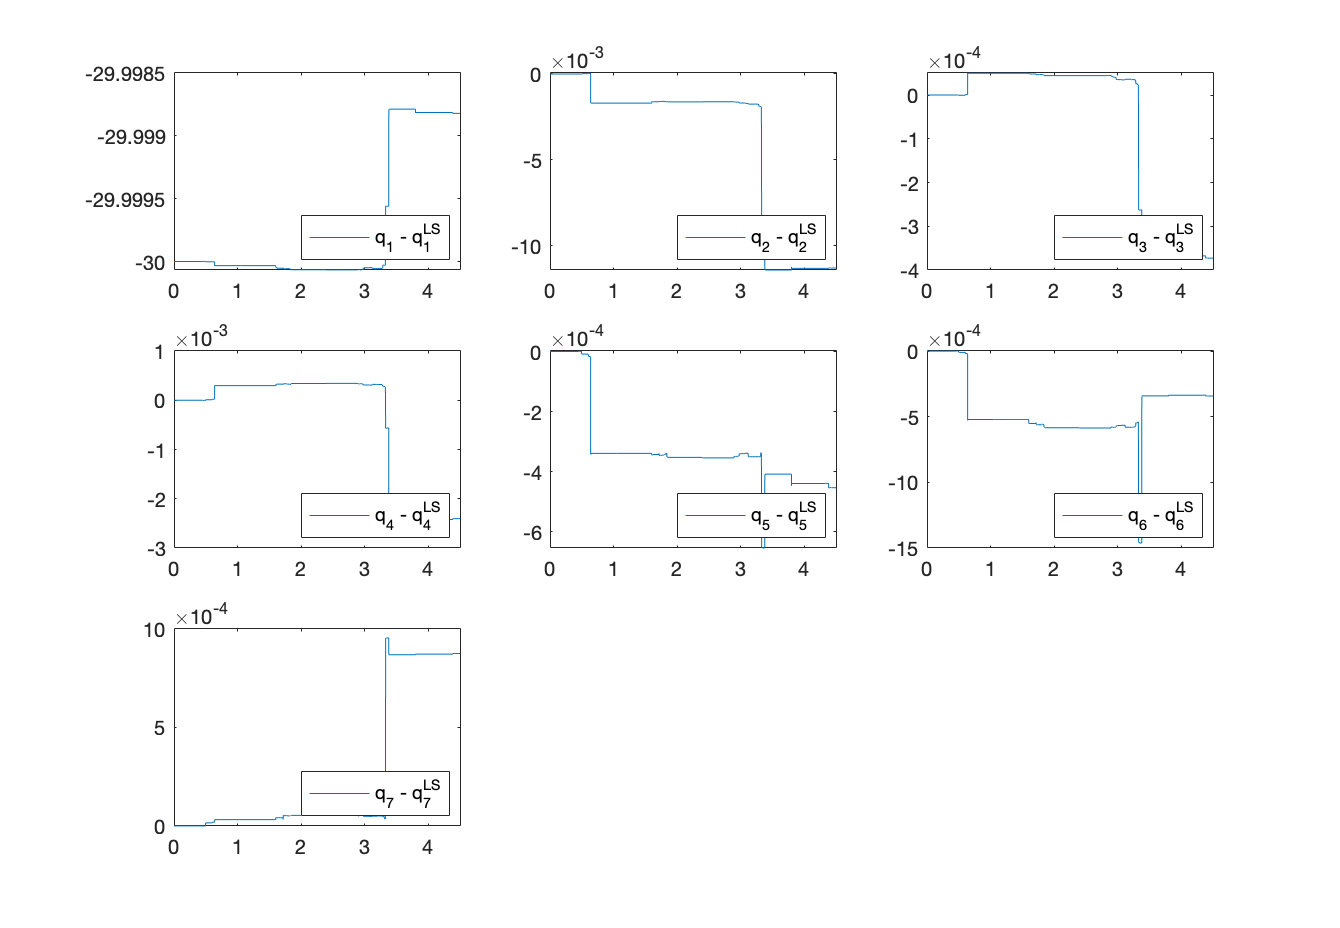

% Model IC 
q0_model = zeros(n, 1);
% LS IC
q0_LS = [deg2rad(30);
         zeros(n-1, 1)];

% Results
LS_KF_EKF_NLDM("LS", 'free', [], [], 'S1_F0_H3');

# KALMAN FILTER ON LINEARIZED DISCRETE STATE-SPACE MODEL

## 1.  Discrete Non Linear model (Ts = 10ms)

Runge-Kutta discretization method is applied to the continuos NL model. The sampling time Ts = 10ms was chosen.


$$\begin{cases}
\mathbf{q}_{k+1} = \textbf{f}(\mathbf{q}_k, \mathbf{\tilde{u}}_k)   \\
\mathbf{p}_k = \mathbf{\Phi}(\mathbf{q}_k) 
+  \mathbf{v}_k \\
\end{cases} \qquad , \quad 

\begin{cases}
\mathbf{\tilde{u}}_k \sim \mathcal{N}(0, \mathbf{N_u})\\
\mathbf{v}_k \sim \mathcal{N}(0, \mathbf{R})
\end{cases} \\
\textbf{f} = \mathbf{q}_k + \frac{1}{6}  \cdot T_s  \cdot (\mathbf{k_1} + 2\mathbf{k_2} + 2\mathbf{k_3} + \mathbf{k_4})
\\
\\
\mathbf{k_1} = \mathbf{J}^{\dagger}(\mathbf{q}_k)\cdot \mathbf{\tilde{u}}_k  \\
\mathbf{k_2} = \mathbf{J}^{\dagger}(\mathbf{q}_k + T_s  \cdot  \frac{k_1}{2})\cdot \mathbf{\tilde{u}}_k  \\
\mathbf{k_3} = \mathbf{J}^{\dagger}(\mathbf{q}_k + T_s  \cdot  \frac{k_2}{2})\cdot \mathbf{\tilde{u}_k  \\
\mathbf{k_4} = \mathbf{J}^{\dagger}(\mathbf{q}_k + T_s  \cdot  k_3)\cdot \mathbf{\tilde{u}}_k$$


The comparison between the simulation and the discrete Non Linear model is reported below.

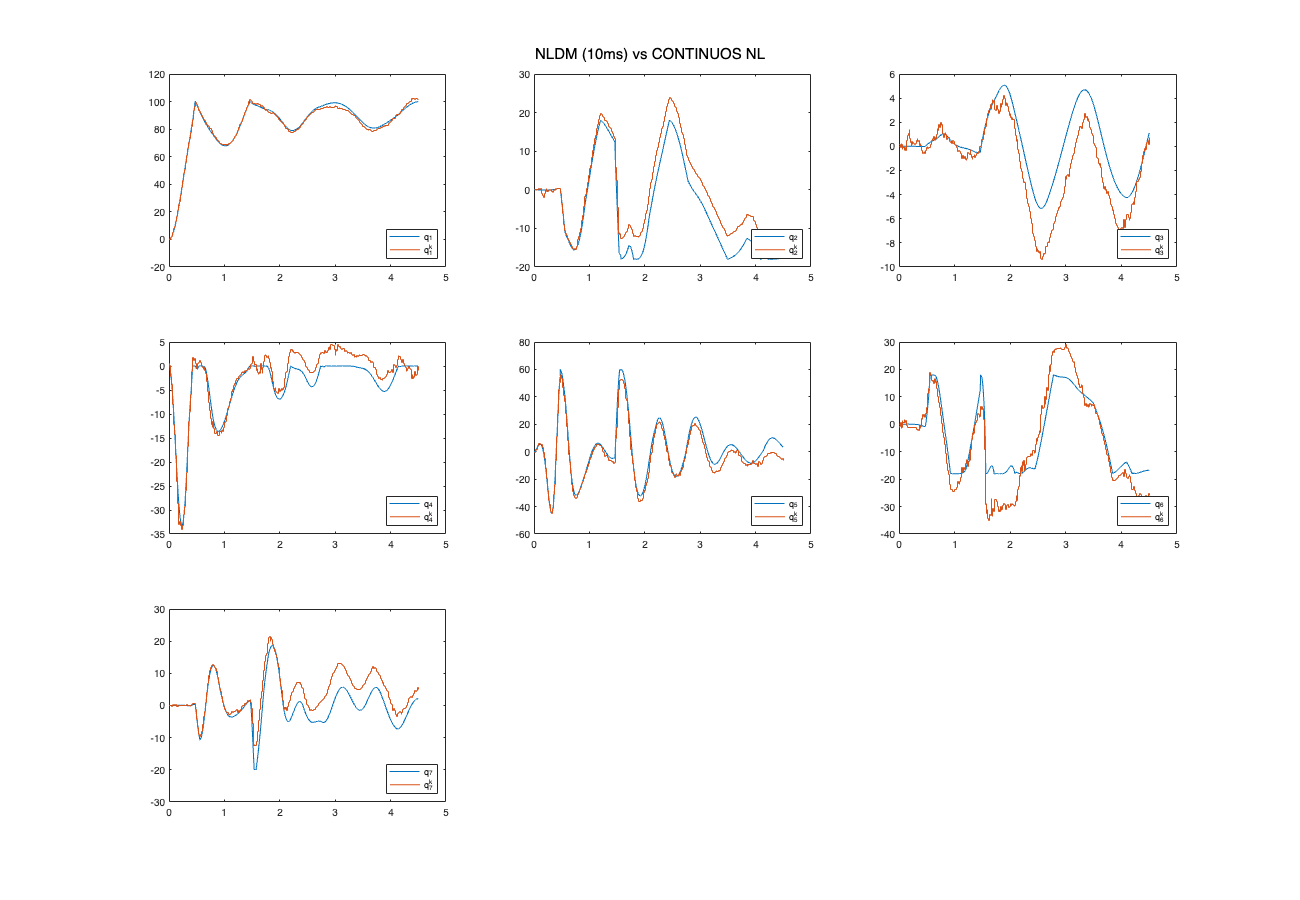

% Clear variables
clear;
clear global;
close all;
clc;

% Human arm parameters
run('human_arm_param.m');

% Model IC 
q0_model = zeros(n, 1);

% Sample time is fixed at 0.01
LS_KF_EKF_NLDM("NLDM", 'free', [], [], 'S4_F3_H2');

## 2.  Linearized Discrete model around equilibrium point

The Discrete state-space model is computed by linearizing the discrete NL model around a given equilibrium point.                                                


$$\begin{cases}
\mathbf{\Delta q}_{k+1} = \mathbf{F}\cdot \mathbf{\Delta q}_k + \mathbf{G}\cdot \mathbf{\Delta \tilde{u}}_k  + \mathbf{w}_k \\
\mathbf{\Delta p}_k = \mathbf{H}\cdot\mathbf{\Delta q}_k  + \mathbf{v}_k\\
\end{cases} \qquad , \quad 
\begin{cases}
\mathbf{\Delta q}_{k} = \mathbf{q}_k - \mathbf{q}_{eq} \\
\mathbf{\Delta \tilde{u}}_{k} = \mathbf{\tilde{u}}_k - \mathbf{u}_{eq} \\
\mathbf{\tilde{u}}_k = \mathbf{\bar{u}}_k + \mathbf{n}_k
\end{cases} \qquad , \quad \begin{cases}
\mathbf{w}_k \sim \mathcal{N}(0, \mathbf{Q})\\
\mathbf{v}_k \sim \mathcal{N}(0, \mathbf{R})
\end{cases}$$


where,


$$\\
\mathbf{F} = \nabla_q\textbf{f}|_{q_{eq}, u_{eq}} \\
\mathbf{G} = \nabla_u\textbf{f}|_{q_{eq}, u_{eq}} \\
\mathbf{H} = \nabla_q\mathbf{\Phi}|_{q_{eq}}$$


## 3.  Kalman Filter on the linearized discrete state-space model

The Discrete state-space model is computed by linearizing the discrete NL model around the given equilibrium point.                                              


$$\begin{cases}
\mathbf{\Delta q}_{k+1} = \mathbf{F}\cdot \mathbf{\Delta q}_k + \mathbf{G}\cdot \mathbf{\Delta \tilde{u}}_k  + \mathbf{w}_k \\
\mathbf{\Delta p}_k = \mathbf{H}\cdot\mathbf{\Delta q}_k  + \mathbf{v}_k\\
\end{cases} \qquad , \quad \begin{cases}
\mathbf{w}_k \sim \mathcal{N}(0, \mathbf{Q})\\
\mathbf{v}_k \sim \mathcal{N}(0, \mathbf{R})
\end{cases}$$


In simulink, the above state space representaion was implemented. Th considered input was  $\mathbf{\Delta \tilde{u}}_k + \mathbf{n}_k$, so that $\mathbf{\Delta q}_{k+1} = \mathbf{F}\cdot \mathbf{\Delta q}_k + \mathbf{G}\cdot (\mathbf{\Delta \tilde{u}}_k  + \mathbf{n}_k)$,            $\mathbf{n}_k \sim \mathcal{N}(0, \mathbf{N})$

The matrix $\mathbf{N}$ was computed such that $\mathbf{GNG^T} = \mathbf{Q}$

### 3.1 Free fall motion, eq. point (q_eq = 0, u_eq = 0)

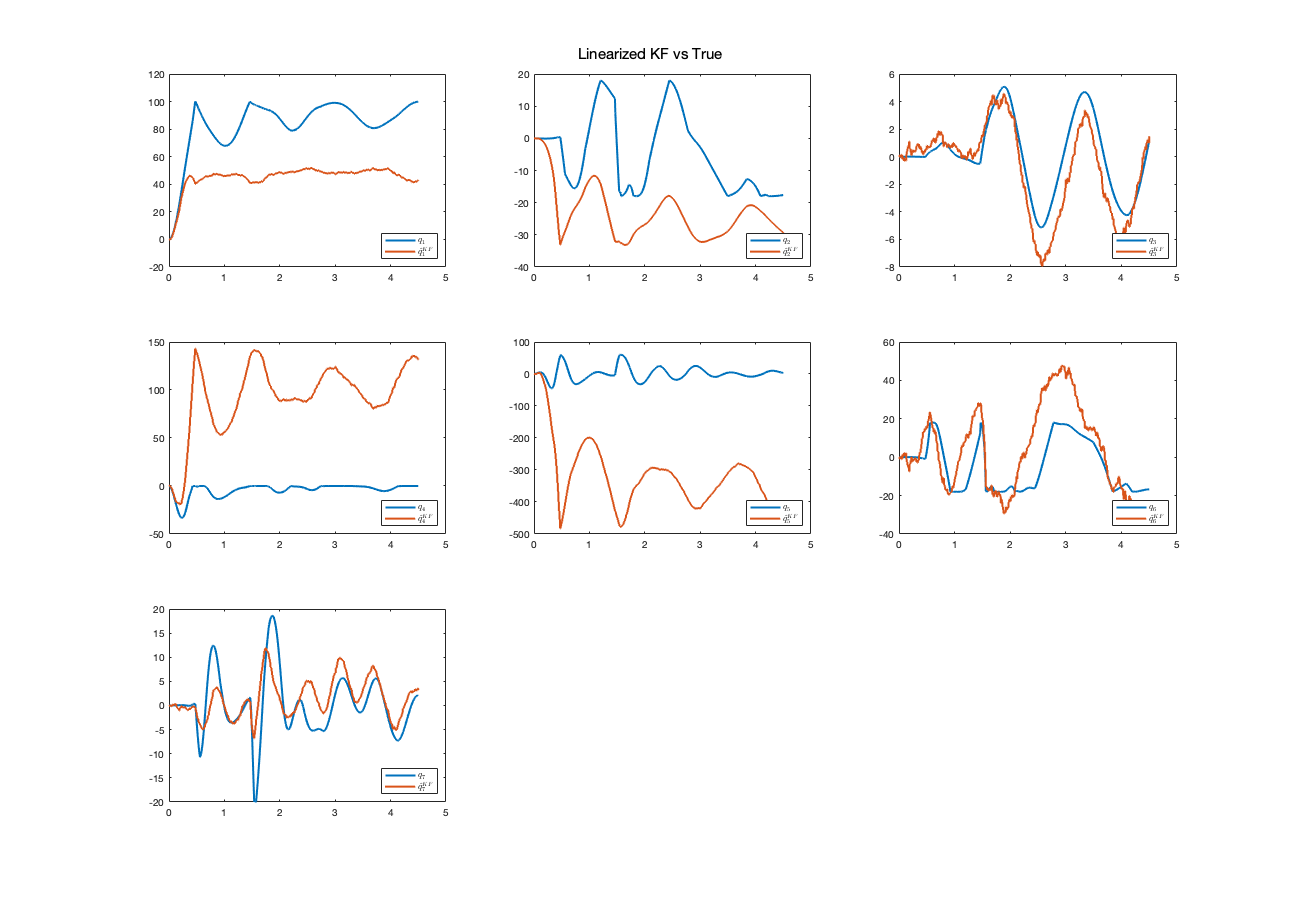

% Clear variables
clear;
clear global;
close all;
clc;

% Human arm parameters
run('human_arm_param.m');

% Model IC
q0_model = zeros(n, 1);

% Equilibrium point
kf.q_eq = zeros(n, 1);
kf.u_eq = zeros(3*m, 1);

% Initial estimate Delta_q0
kf.Delta_q0 = zeros(n, 1);

% Initial covariance estimate P0
kf.P0 = 10 * eye(n);

% Results
LS_KF_EKF_NLDM("KF", 'free', marker, number_samples, 'S4_F3_H2');

### 3.2 Human arm motion close to the rest position

The discrete NL model is now linearized around the rest position of the human arm, i.e. when the human arm is perpendicular to the ground.

In this context all initial joints' variables are assumed to be set to 0°, except for $q_1$ which is set to 87°.


$$q_0 = \pmatrix{87\degree  \cr 0\degree  \cr ..  \cr 0\degree } , \qquad q_{eq} =  \pmatrix{90 \degree  \cr 0\degree  \cr ..  \cr 0\degree },  \qquad u_{eq} =  \pmatrix{ 0  \cr 0  \cr ..  \cr 0 } $$


The model is now expected to simulate better the human arm motion.

The comparison between simulation and linearized discrete state-space is reported below.

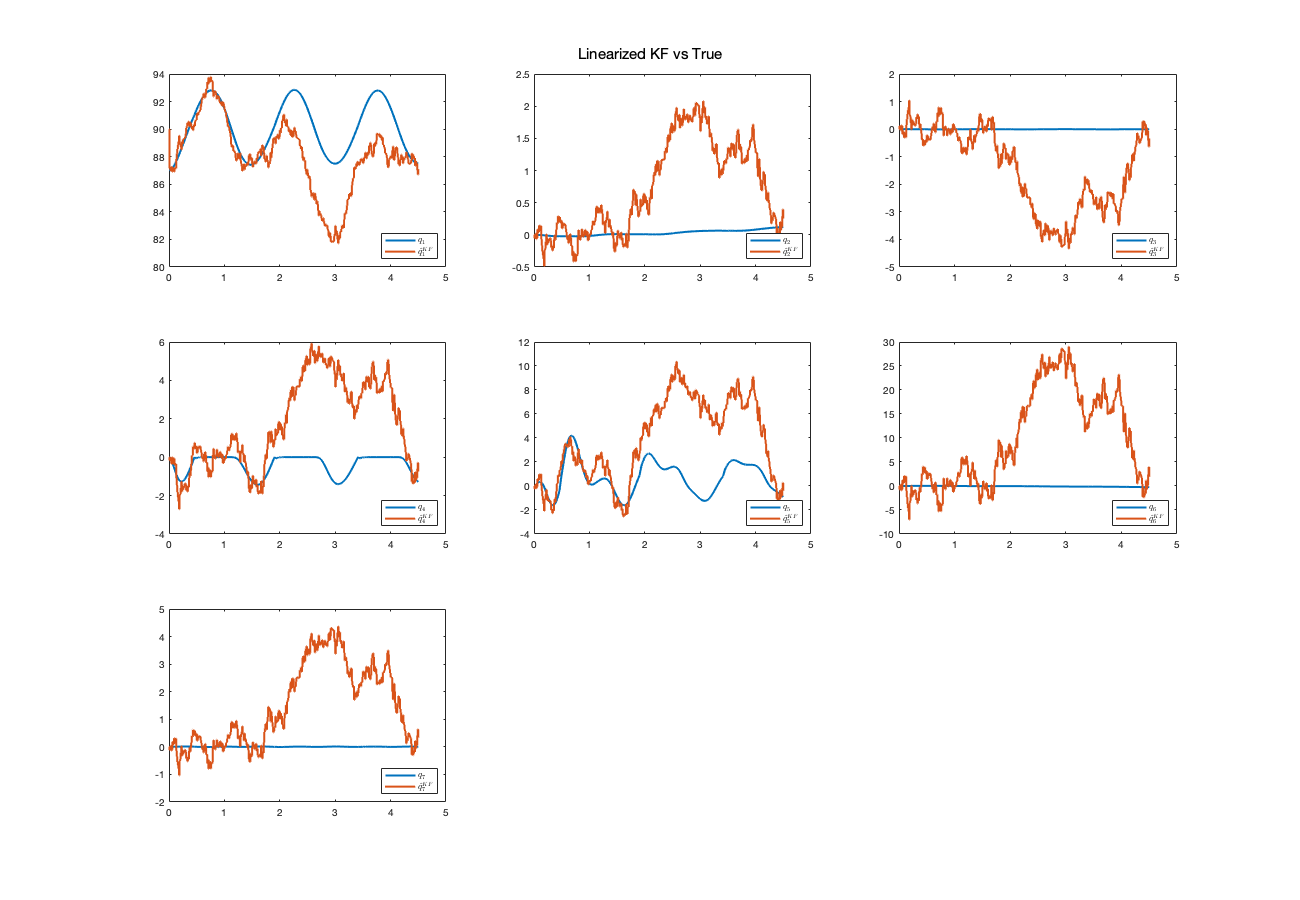

% Model IC
q0_model = [deg2rad(87); zeros(n-1, 1)];

% Equilibrium point
kf.q_eq = [pi/2; zeros(n-1, 1)];
kf.u_eq = zeros(3*m, 1);

% Initial estimate Delta_q0
kf.Delta_q0 = zeros(n, 1);

% Initial covariance estimate P0
kf.P0 = 10 * eye(n);

% Results
LS_KF_EKF_NLDM("KF", 'free', marker, number_samples, 'S4_F3_H2');

# EXTENDED KALMAN FILTER

## 1.  Discrete Non Linear model


$$\begin{cases}
\mathbf{q}_{k} = \textbf{f}(\mathbf{q}_{k-1}, \mathbf{u}_{k-1}) + \mathbf{w}_{k-1}  \\
\mathbf{p}_k = \mathbf{\Phi}(\mathbf{q}_k) + \mathbf{v}_k \\
\end{cases}  \qquad , \quad 
\begin{cases}
\mathbf{w}_k \sim \mathcal{N}(0, \mathbf{Q})\\
\mathbf{v}_k \sim \mathcal{N}(0, \mathbf{R})
\end{cases}$$


We perform a Taylor series expansion of the state equation around $\mathbf{q}_{k-1} = \hat{\mathbf{q}}_{k-1}^+$ and we obtain:


$$\mathbf{q}_{k} = \mathbf{f}\left(\hat{\mathbf{q}}_{k-1}^+, \mathbf{u}_{k-1}\right) + \left.\frac{\partial \mathbf{f}}{\partial \mathbf{q}}\right|_{\hat{\mathbf{q}}_{k-1}^{+}, \mathbf{u}_{k-1}}\left(\mathbf{q}_{k-1}-\hat{\mathbf{q}}_{k-1}^{+}\right) + \mathbf{w}_{k-1} \\ =
\mathbf{f}\left(\hat{\mathbf{q}}_{k-1}^{+}, \mathbf{u}_{k-1}\right)+\mathbf{F}_{k-1}\left(\mathbf{q}_{k-1}-\hat{\mathbf{q}}_{k-1}^{+}\right) + \mathbf{w}_{k-1} \\ =

\mathbf{F}_{k-1} \mathbf{q}_{k-1}+\left[\mathbf{f}\left(\hat{\mathbf{q}}_{k-1}^{+}, \mathbf{u}_{k-1}\right)-\mathbf{F}_{k-1} \hat{\mathbf{q}}_{k-1}^{+}\right] + \mathbf{w}_{k-1} \\ =
\mathbf{F}_{k-1} \mathbf{q}_{k-1}+\mathbf{r}_{k-1}+\mathbf{w}_{k-1}$$


We linearize the measurement equation around $\mathbf{q}_k = \hat{\mathbf{q}}_k^-$ and we obtain:


$$\mathbf{p}_{k} = \mathbf{\Phi}\left(\hat{\mathbf{q}}_k^-\right) + \left.\frac{\partial \mathbf{\Phi}}{\partial \mathbf{q}}\right|_{\hat{\mathbf{q}}_{k}^{-}}\left(\mathbf{q}_{k}-\hat{\mathbf{q}}_{k}^{-}\right)+ \mathbf{v}_{k} \\ =

\mathbf{\Phi}\left(\hat{\mathbf{q}}_k^-\right) + \mathbf{H}_{k}\left(\mathbf{q}_{k}-\hat{\mathbf{q}}_{k}^{-}\right)+ \mathbf{v}_{k} \\ =

\mathbf{H}_{k}\mathbf{q}_{k}+\left[\mathbf{\Phi}\left(\hat{\mathbf{q}}_{k}^{-}\right)-\mathbf{H}_{k}\hat{\mathbf{q}}_{k}^{-}\right]+\mathbf{v}_k \\ =
\mathbf{H}_{k} \mathbf{q}_{k}+\mathbf{z}_{k}+\mathbf{v}_{k}$$
				

We can use the standard Kalman Filter equations to estimate the state.

In summary, the following steps are performed to compute the KF estimate at each step.

- The system and measurement equations are given as follows 

          
$$\begin{cases}
\mathbf{q}_{k} = \textbf{f}(\mathbf{q}_{k-1}, \mathbf{u}_{k-1}) + \mathbf{w}_{k-1}  \\
\mathbf{p}_k = \mathbf{\Phi}(\mathbf{q}_k) + \mathbf{v}_k \\
\end{cases}  \qquad , \quad 
\begin{cases}
\mathbf{w}_k \sim \mathcal{N}(0, \mathbf{Q})\\
\mathbf{v}_k \sim \mathcal{N}(0, \mathbf{R})
\end{cases}$$


- Initialize the filter as follows  $\hat{\mathbf{q}}_{0}^+ = \mathbb{E}(\mathbf{q}_0) \quad, \quad
\mathbf{P}_0^+ = \mathbb{E}[(\mathbf{q}_0 - \hat{\mathbf{q}}_{0}^+)(\mathbf{q}_0 - \hat{\mathbf{q}}_{0}^+)^T]$ 

- For k = 1, 2, .. perform the following 

                          
$$\mathbf{F}_{k-1} =  \left.\frac{\partial \mathbf{f}}{\partial \mathbf{q}}\right|_{\hat{\mathbf{q}}_{k-1}^{+},\mathbf{u}_{k-1}
$$


                            **TIME UPDATE**

                            
$$\mathbf{P}_k^- = \mathbf{F}_{k-1}\mathbf{P}_{k-1}^+\mathbf{F}_{k-1}^T + \mathbf{Q} \\
\hat{\mathbf{q}}_k^- = \mathbf{f}(\hat{\mathbf{q}}_{k-1}^+, \mathbf{u}_{k-1})$$


                             
$$\mathbf{H}_{k} =  \left.\frac{\partial \mathbf{\Phi}}{\partial \mathbf{q}}\right|_{\hat{\mathbf{q}}_{k}^{-}$$


                            **MEASUREMENT UPDATE**

                            
$$\mathbf{K}_k = \mathbf{P}_{k}^-\mathbf{H}_{k}^T(\mathbf{H}_k\mathbf{P}_k^-\mathbf{H}_k^T + \mathbf{R})^{-1}
\\
\hat{\mathbf{q}}_k^+ = \hat{\mathbf{q}}_k^- + \mathbf{K}_k[\textbf{p}_k - \mathbf{\Phi}(\hat{\mathbf{q}}_k^-)]
\\
\mathbf{P}_k^+ = (\mathbf{I} - \mathbf{K}_k\mathbf{H}_k)\mathbf{P}_k^-$$


A new example is now considered.

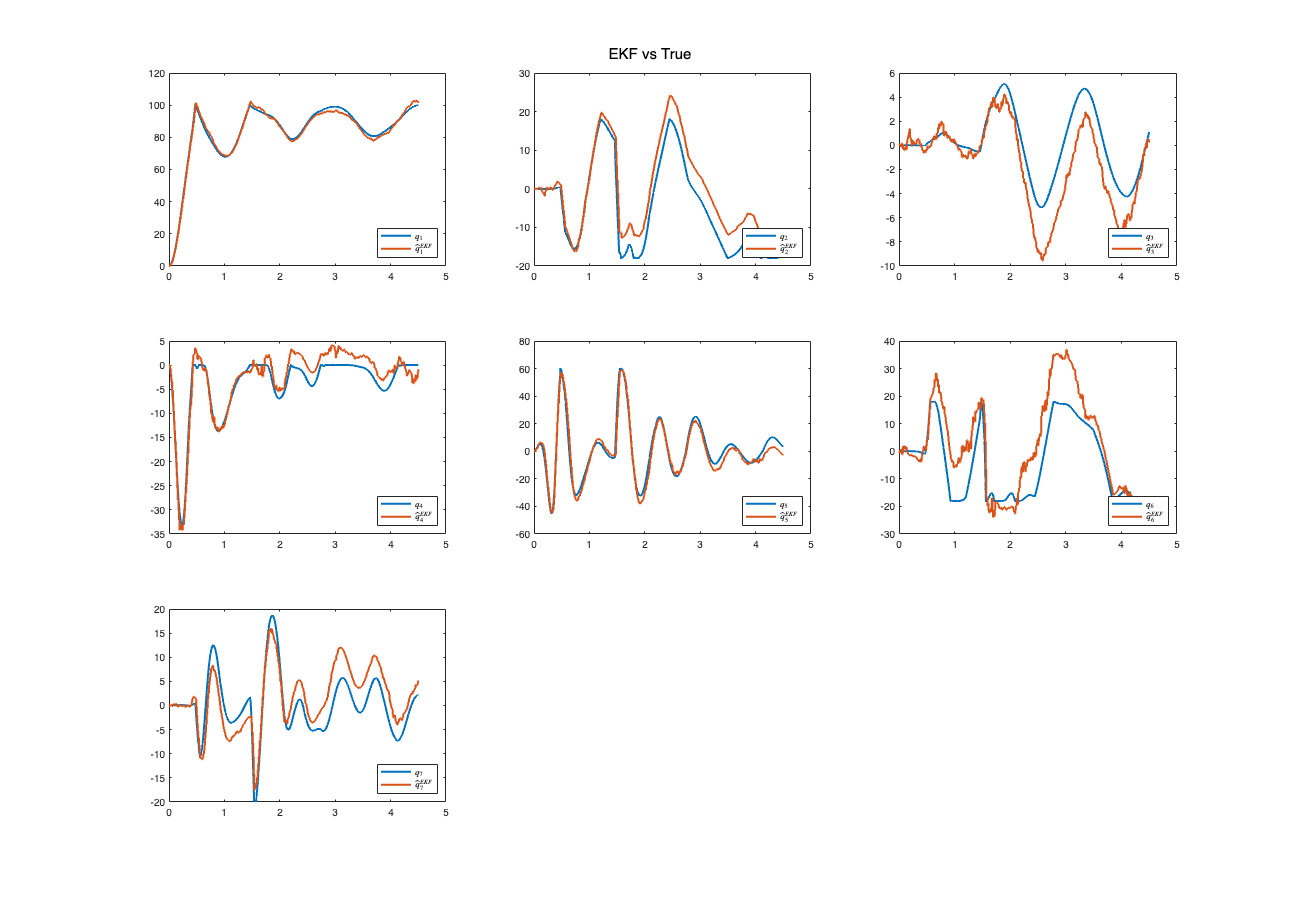

% Clear variables
clear;
clear global;
close all;
clc;

% Human arm parameters
run('human_arm_param.m');

% Model IC
q0_model = [deg2rad(0); zeros(n-1, 1)];

% Initial estimate q0
ekf.q0 = zeros(n, 1);

% Initial covariance estimate P0
ekf.P0 = 10 * eye(n);

% Results
LS_KF_EKF_NLDM("EKF", 'free', marker, number_samples, 'S4_F3_H2');

# Comparison between Methods

% Clear variables
clear;
clear global;
close all;
clc;

% Human arm parameters
run('human_arm_param.m');

% Model IC
q0_model = [deg2rad(0); 0 * ones(n-1, 1)];

## LS

% LS IC
q0_LS = zeros(n, 1);

## KF

% Equilibrium point
kf.q_eq = [pi/2; zeros(n-1, 1)];
kf.u_eq = zeros(3*m, 1);

% Initial estimate Delta_q0
kf.Delta_q0 = zeros(n, 1);

% Initial covariance estimate P0
kf.P0 = 1 * eye(n);

## EKF

% Initial estimate q0
ekf.q0 = zeros(n, 1);

% Initial covariance estimate P0
ekf.P0 = diag([1; 0.000001 * ones(n-1, 1)]);


## Results

     0

     0

     0

     0

     0

     0

     0

     0

     0

     0

     0

     0

     0

     0

     0

     0

    0.0020

    0.0030

    0.0080

    0.0100

   4.2568e-04

   6.3853e-04

    0.0017

    0.0019

    0.0021

    0.0021

   2.1284e-04

   3.1926e-04

   8.5137e-04

   9.4597e-04

    0.0011

    0.0011

   1.0642e-04

   1.5963e-04

   4.2568e-04

   4.7298e-04

   5.3211e-04

   5.3211e-04

   5.3211e-05

   7.9816e-05

   2.1284e-04

   2.3649e-04

   2.6605e-04

   2.6605e-04

   2.6605e-04

   3.1926e-04

   3.4587e-04

   4.7889e-04

   5.0254e-04

   5.3211e-04

   5.3211e-04

   5.3211e-04

   6.1526e-04

   6.5684e-04

   8.6472e-04

   9.0168e-04

   9.4788e-04

   9.4788e-04

   9.4788e-04

    0.0011

    0.0011

    0.0014

    0.0014

    0.0015

    0.0015

    0.0015

    0.0016

    0.0017

    0.0020

    0.0020

    0.0021

    0.0021

    0.0021

    0.0023

    0.0024

    0.0028

    0.0028

    0.0029

    0.0029

    0.0029

    0

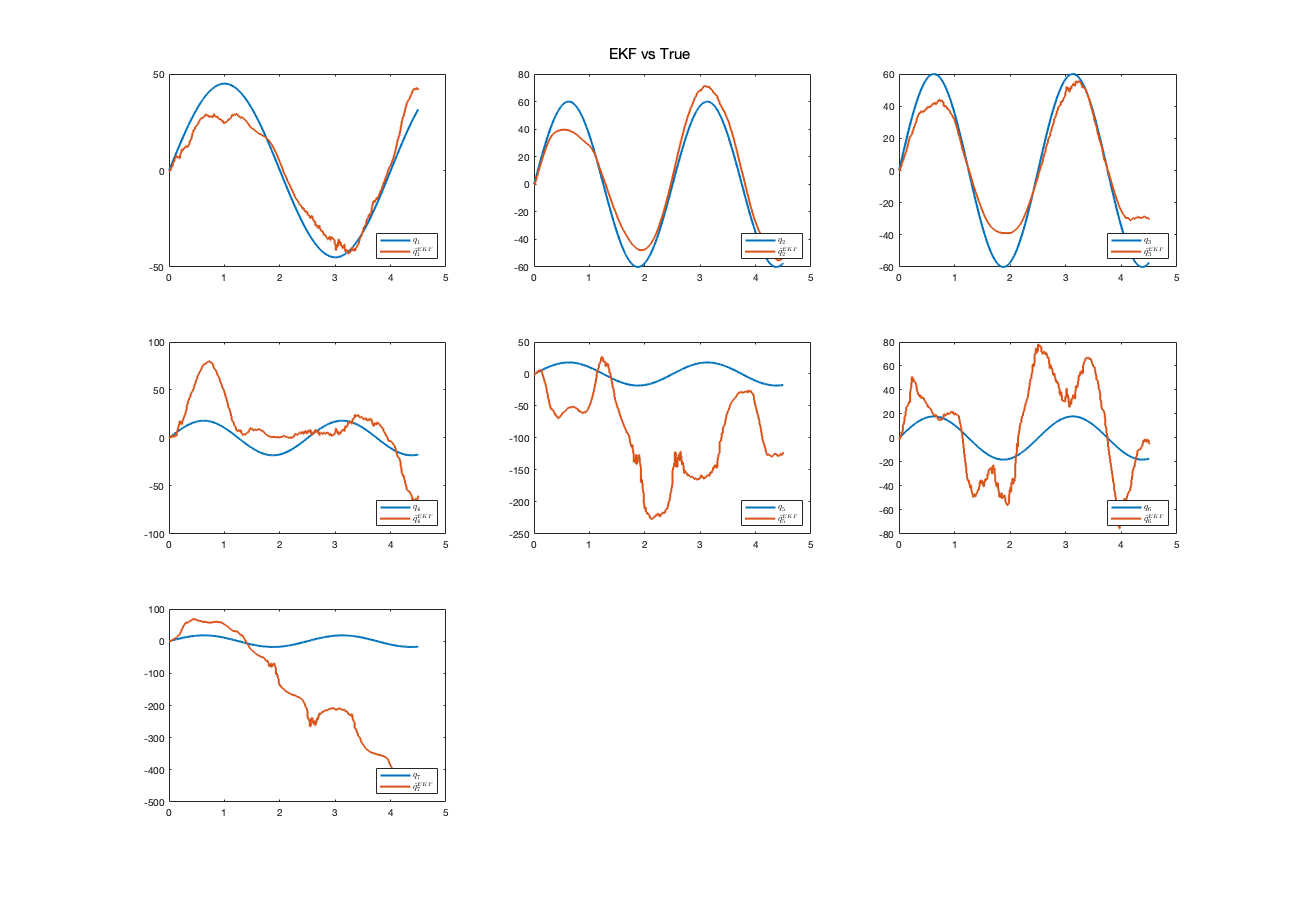

noise.Q =  0.0000000001 * diag(ones(n, 1));
%noise.R = 0.001 * diag(ones(m*3, 1));  
% noise.Nu = 0.00000285 * diag(ones(m*3, 1));

LS_KF_EKF_NLDM(["EKF"], 'precomputed', marker, number_samples, 'S4_F3_H2');